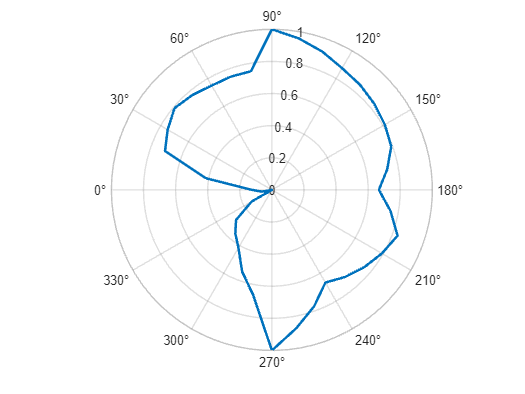

% Kąty w stopniach
angles_deg = 0:10:360;

% Przykładowe wartości dBFS
% 0 - 360
dbfs = [-14.5, -11, -7.5, -7, -6.5, -6.75, -7, -7, -7, -4, -4.5, -5, -5.5, -5.75, -6, -6.25, -6.5, -7.25, -8, -7, -6, - 6.5, -7, -7.5, -8, -6.75, -5.5, -4, -8, -9.5, -11, -11.75, -12.5, -14.25, -16, -15.25, -14.5];
%ax.ThetaZeroLocation = 'right'; % 0° po lewej
%ax.ThetaDir = 'counterclockwise';     % kąty rosną zgodnie z ruchem wskazówek zegara
%dbfs = [-8, -7.25, -6.5, -6.25, -6, -5.75, -5.5, -5, -4.5, -4, -7, -7, -7, -6.75, -6.5, -7, -7.5, -11, -14.5, -15.25, -16, -14.25, -12.5, -11.75, -11, -9.5, -8, -4, -5.5, -6.75, -8, -7.5, -7, -6.5, -6, -7, -8];
%dbfs = [-8, -7.25, -6.5, -6.25, -6, -5.75, -5.5, -5, -4.5, -4, -7, -7, -7, -6.75, -6.5, -7, -7.5, -11, -14.5, -15.25, -16, -14.25, -12.5, -11.75, -11, -9.5, -8, -4, -5.5, -6.75, -8, -7.5, -7, -6.5, -6, -7, -8];


% Zamiana stopni na radiany
angles_rad = deg2rad(angles_deg);

% Normalizacja wartości
r = dbfs - min(dbfs);
r = r / (max(r) - min(r));

% Tworzenie wykresu biegunowego
ax = polaraxes;
polarplot(ax, angles_rad, r, 'LineWidth', 2);

% Ustawienie kątów osi
ax.ThetaZeroLocation = 'left'; % 0° po lewej
ax.ThetaDir = 'clockwise';     % kąty rosną zgodnie z ruchem wskazówek zegara